# Example 2

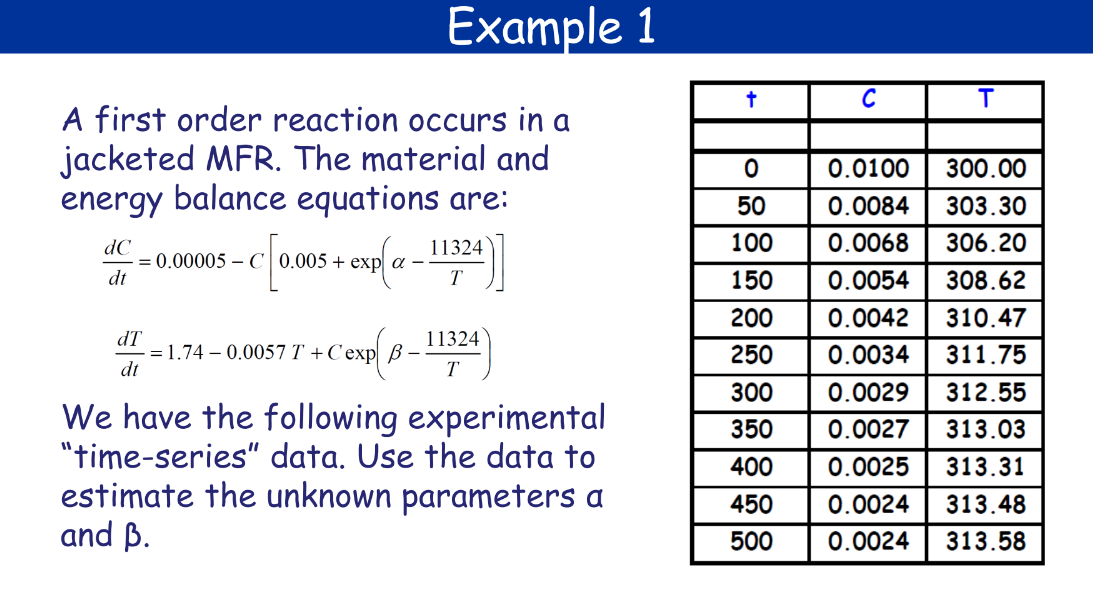

clear;clc;
t=linspace(0,500,11);
C_Theo=[0.01,0.0084,0.0068,0.0054,0.0042,0.0034,0.0029,0.0027,0.0025,0.0024,0.0024];
T_Theo=[300, 303.30,306.20,308.62,310.47,311.75,312.55,313.03,313.31,313.48,313.58];
dT_dt=zeros(11,1);
dC_dt=zeros(11,1);
dT_dt(1)=(T_Theo(2)-T_Theo(1))/(t(2)-t(1));
dC_dt(1)=(C_Theo(2)-C_Theo(1))/(t(2)-t(1));
for i=2:10
    dT_dt(i)=(T_Theo(i+1)-T_Theo(i-1))/(t(i+1)-t(i-1));
    dC_dt(i)=(C_Theo(i+1)-C_Theo(i-1))/(t(i+1)-t(i-1));
end
dT_dt(11)=(T_Theo(11)-T_Theo(10))/(t(11)-t(10));
dC_dt(11)=(C_Theo(11)-C_Theo(10))/(t(11)-t(10));

inguess=[100,50];
[x,f]=fmincon(@(param)pred1(param,C_Theo,T_Theo,dT_dt,dC_dt),inguess,[],[],[],[],[],[],[],optimset("display",'off'));
% Predictor Function
function y=pred(param,C,T)
    a=param(1);
    b=param(2);
    y(1)=0.0005-C*(0.005+exp(a-11324/T));
    y(2)=1.74-0.0057*T+C*exp(b-11324/T);
end
% Error Function: Returns predicted-true
function errorx=pred1(param,C,T,dT_dt,dC_dt)
    error=zeros(2,11);
    %disp(error)
    for i=1:11
        pct=pred(param,C(i),T(i));
        error(i,1)=abs(pct(1)-dC_dt(i));
        error(i,2)=abs(pct(2)-dT_dt(i));
        %disp(error);
    end
    cnt1=0;
    cnt2=0;
    for i=1:11
        cnt1=cnt1+error(i,1);
        cnt2=cnt2+error(i,2);
    end
    cnt1=sqrt(cnt1/11);
    cnt2=sqrt(cnt2/11);

    errorx=cnt1*cnt2;
end

## ETE 2022+2023 ka question

clear;clc;
x=linspace(35,50,16);
y=[405 285 207 154 118 93 74 60 49 41 35 30 26 22 20 17];

[x,f]=fmincon(@(param)err(param,x,y),[-1 140 15],[],[],[],[],[],[],[],optimset("Display",'off'))

x =    -1.2630  142.5514   15.3842


f = 0.2974

disp("Parameters are: ")

Parameters are: 


disp(x(1))

   -1.2630



disp(x(2))

  142.5514



disp(x(3))

   15.3842



function errorx=err(param,x,y)
    errorx=rmse(prediction(param,x),y);
    %errorx=sqrt(mean((y-prediction(param,x)).^2));
end
function y=prediction(param,x)
    a=param(1);
    b=param(2);
    c=param(3);
    y=exp(a+b./(x-c));
end